# Deconvolution Benchmark 2D: Matlab (DL2)

javaaddpath([matlabroot filesep 'java' filesep 'DeconvolutionLab_2.jar']);

addpath('/Users/yi/npy-matlab-master/npy-matlab'); % para poder cargar ficheros .npy


% Definir la carpeta donde se encuentran las imágenes que se van a emplear
folder = 'ImagenesEmpleadas2D';

## Test Image 2D

% Cargar la imagen y la PSF
img_test = single(readNPY(fullfile(folder, 'imagen_borrosa.npy')));
psf_test = single(readNPY(fullfile(folder, 'test_psf.npy')));

result_test = DL2.RL(img_test, psf_test, 30, '-out')

Log   	 254,38 us 	  658,9Mb  	 DeconvolutionLab2 2.1.2 (27.06.2018) on Matlab
Log   	 975,50 us 	  693,0Mb  	 AcademicFFT Added
Log   	 12,25 ms 	  693,0Mb  	 JTransforms not found
Log   	 19,82 ms 	  694,4Mb  	 FFTW Widsom not found in : /Applications/MATLAB_R2024b.app/java/FFTW/
Log   	 19,95 ms 	  694,4Mb  	 FFTW Widsom not found in : /Applications/MATLAB_R2024b.app/java/
Log   	 20,03 ms 	  694,4Mb  	 FFTW Widsom not found in : /Users/yi/FFTW/
Log   	 20,09 ms 	  694,4Mb  	 FFTW Widsom not found in : /Users/yi/
Log   	 20,14 ms 	  694,4Mb  	 FFTW not found


result_test =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0

Visualización y guardado del resultado:

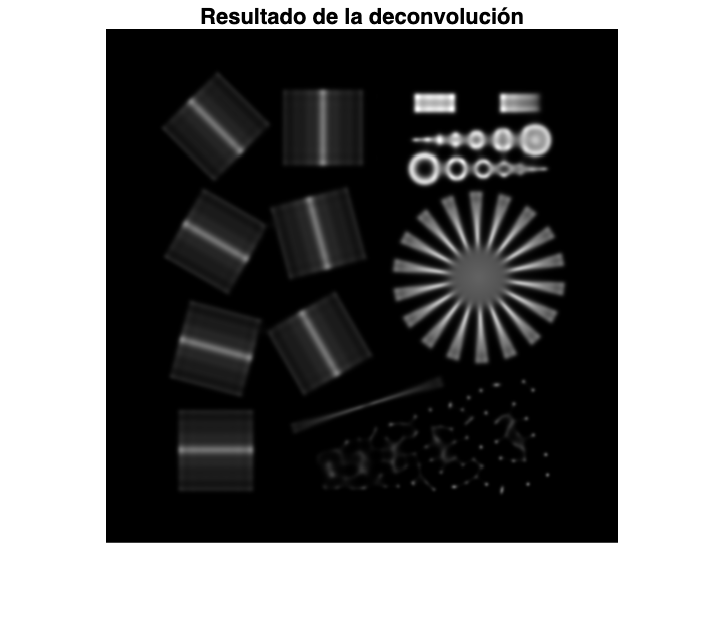

figure;
imshow(result_test, []);  % El [] ajusta automáticamente el rango de intensidad
colormap gray;            % Escala de grises
title('Resultado de la deconvolución');

imwrite(mat2gray(result_test), '2D_MATLAB_imagetest_DL2.png');  % mat2gray normaliza a [0,1]


### @ BENCHMARK

% ------------------------------
% Configuración
% ------------------------------
numIter = 10;                           % Número de ejecuciones
csvFile = 'RL_times_test.csv';               % Nombre del CSV de salida

% Eliminar archivo previo si existe
if exist(csvFile, 'file')
    delete(csvFile);
end

% ------------------------------
% Bucle de ejecución
% ------------------------------
T_test = zeros(numIter,1);  % Vector para guardar tiempos

for i = 1:numIter
    tic
    result_test = DL2.RL(img_test, psf_test, 30, '-out');  % Ejecutar deconvolución
    T_test(i) = toc;  % Guardar tiempo total
    
    % Guardar inmediatamente en CSV
    writematrix(T_test(i), csvFile, 'WriteMode', 'append');
    
    fprintf('Iteración %d: %.3f s\n', i, T_test(i));
end

Iteración 1: 2.709 s
Iteración 2: 2.598 s
Iteración 3: 2.625 s
Iteración 4: 2.603 s
Iteración 5: 2.552 s
Iteración 6: 2.742 s
Iteración 7: 2.649 s
Iteración 8: 2.621 s
Iteración 9: 2.651 s
Iteración 10: 2.655 s



disp('Todos los tiempos guardados en RL_times.csv');

Todos los tiempos guardados en RL_times.csv


disp(T_test);

    2.7087
    2.5985
    2.6246
    2.6027
    2.5522
    2.7418
    2.6491
    2.6206
    2.6511
    2.6547



medianTime = median(T_test);
fprintf('Tiempo mediano de deconvolución: %.3f s\n', medianTime);

Tiempo mediano de deconvolución: 2.637 s


## Cell 2D

% Cargar la imagen y la PSF
img_cell = single(readNPY(fullfile(folder, '2d_cell_imgborrosa.npy')));
psf_cell = single(readNPY(fullfile(folder, '2d_cell_psf_test.npy')));


result_cell = DL2.RL(img_cell, psf_cell, 30, '-out');

Visualizacion y guardamos imagen:

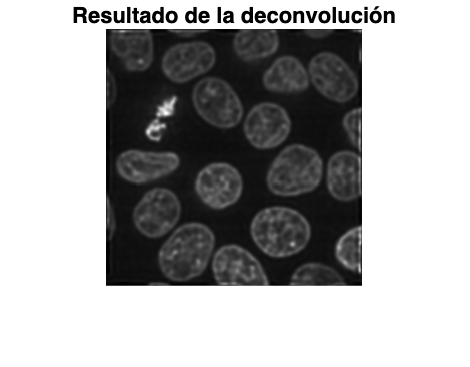

figure;
imshow(result_cell, []);  % El [] ajusta automáticamente el rango de intensidad
colormap gray;            % Escala de grises
title('Resultado de la deconvolución');

imwrite(mat2gray(result_cell), '2D_MATLAB_cell_DL2.png');  % mat2gray normaliza a [0,1]

### @ BENCHMARK

% ------------------------------
% Configuración
% ------------------------------
numIter = 10;                           % Número de ejecuciones
csvFile = 'RL_times_cell.csv';               % Nombre del CSV de salida

% Eliminar archivo previo si existe
if exist(csvFile, 'file')
    delete(csvFile);
end

% ------------------------------
% Bucle de ejecución
% ------------------------------
T_cell = zeros(numIter,1);  % Vector para guardar tiempos

for i = 1:numIter
    tic
    result_cell = DL2.RL(img_cell, psf_cell, 30, '-out');  % Ejecutar deconvolución
    T_cell(i) = toc;  % Guardar tiempo total
    
    % Guardar inmediatamente en CSV
    writematrix(T_cell(i), csvFile, 'WriteMode', 'append');
    
    fprintf('Iteración %d: %.3f s\n', i, T_cell(i));
end

Iteración 1: 1.016 s
Iteración 2: 1.077 s
Iteración 3: 1.034 s
Iteración 4: 1.009 s
Iteración 5: 1.032 s
Iteración 6: 1.006 s
Iteración 7: 1.116 s
Iteración 8: 1.148 s
Iteración 9: 1.082 s
Iteración 10: 1.173 s



disp('Todos los tiempos guardados en RL_times.csv');

Todos los tiempos guardados en RL_times.csv


disp(T_cell);

    1.0163
    1.0766
    1.0340
    1.0094
    1.0323
    1.0060
    1.1165
    1.1480
    1.0816
    1.1735



medianTime_cell = median(T_cell);
fprintf('Tiempo mediano de deconvolución: %.3f s\n', medianTime_cell);

Tiempo mediano de deconvolución: 1.055 s
